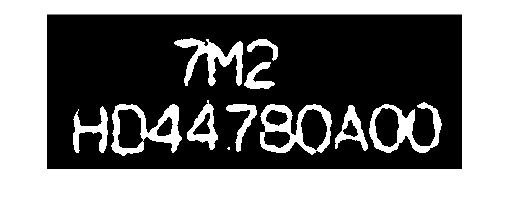

addpath('functions');  % load functions
picture = "./pictures/charact2.jpg";  % load the picture
origin_image = imread(picture);

% use previous functions to do preprocessing
image = rgb2gray(origin_image);
image = contrast(image,0.4, 3);
image = average_filter(image,13);

% change it to binary image
BW = rgb2binary(image, 80);
figure, imshow(BW)

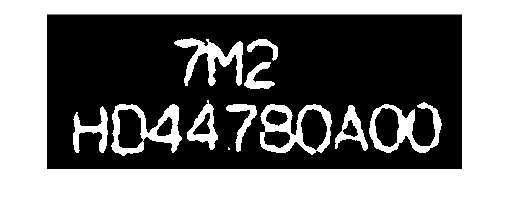


% using 8-connected neighborhood remove some small noise
BW = white_8(BW, 4);
figure, imshow(BW)

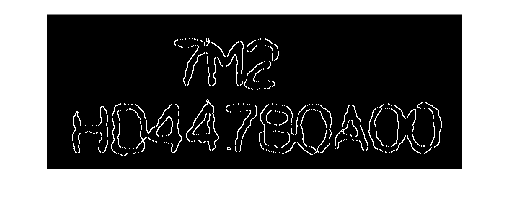

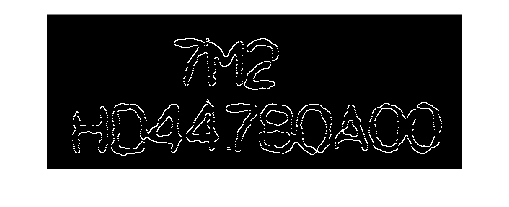


% using sobel operator to find the edge
sobelxy = sobel(BW);

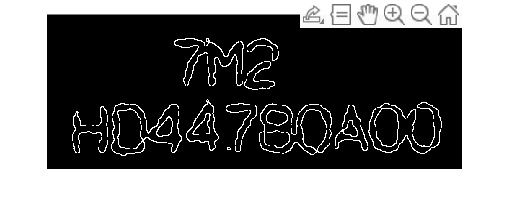

figure, imshow(sobelxy)

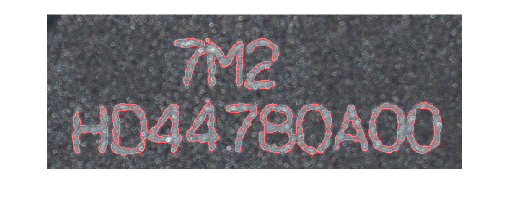


%take it back to original figure
[rows, cols] = size(sobelxy);
for i = 1:rows
    for j = 1:cols
        if sobelxy(i,j) == 255
            origin_image(i,j) = 255;
        end
    end
end
figure, imshow(origin_image)